# File Name: Segmentation_03_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

Load an organized lidar, point cloud.

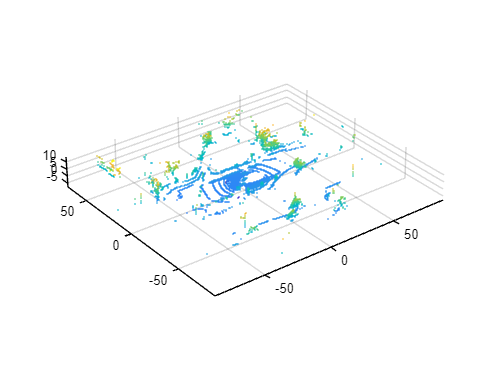

ld = load('drivingLidarPoints.mat');

pcshow (ld.ptCloud)
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])

%%%%%%%%%% TODO %%%%%%%%%%
% Segment ground points from the organized lidar point cloud.
groundPtsIdx = segmentGroundFromLidarData(ld.ptCloud);

%

Create a point cloud containing only these ground points by using the [select](docid:vision_ref#buph2kw-1) function. Display this point cloud.

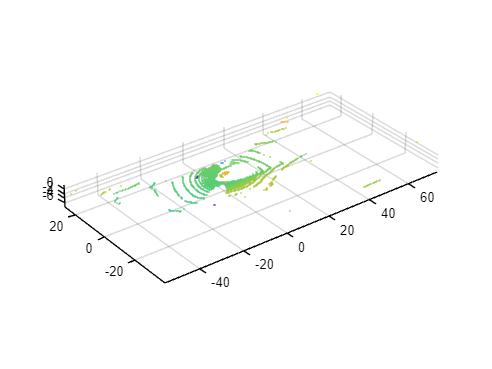

groundPtCloud = select(ld.ptCloud,groundPtsIdx);

figure
pcshow(groundPtCloud)

set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])

Create a point cloud containing only the nonground points.

nonGroundPtCloud = select(ld.ptCloud,~groundPtsIdx);

Display the nonground points cloud clusters.

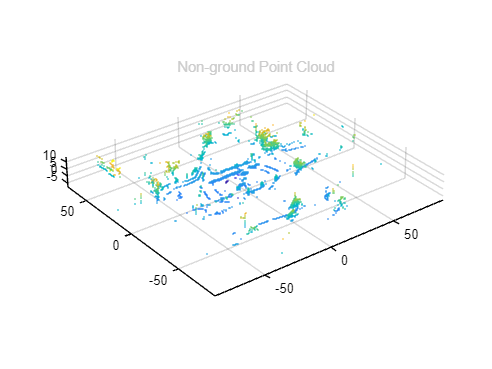

figure
pcshow(nonGroundPtCloud.Location)
title('Non-ground Point Cloud')

set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])